# 需求分析：绘制带有误差线的柱状图

- 单系列带误差线柱状图

- 多系列带误差线柱状图

也有一个开源函数 barweb 可用，链接如下：

[https://ww2.mathworks.cn/matlabcentral/fileexchange/10803-barweb-bargraph-with-error-bars](https://ww2.mathworks.cn/matlabcentral/fileexchange/10803-barweb-bargraph-with-error-bars)

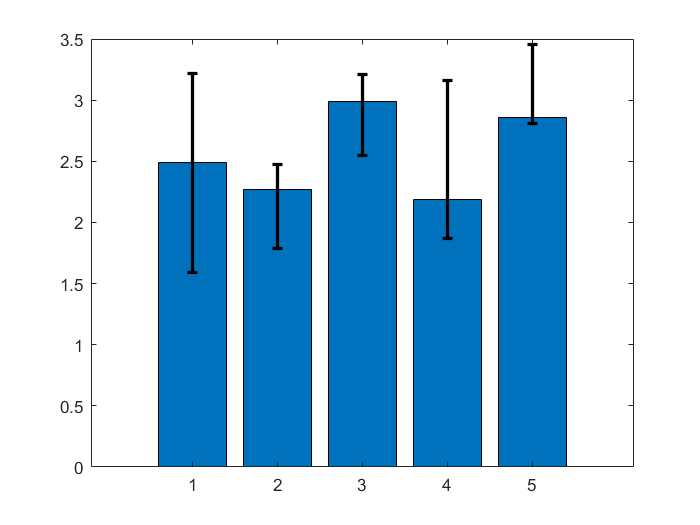

clear;clc;
% 生成示例数据
m = 5;
n = 3;
x = 1:m;
y = rand(m, n) + 2;
% 误差限
neg = rand(m, n);
pos = rand(m, n);
% 单系列带有误差线的柱状图
figure;
bar(x, y(:, 1));
hold on
errorbar(x, y(:, 1), neg(:, 1), pos(:, 1), 'LineStyle', 'none', 'Color', 'k', 'LineWidth', 2);
hold off

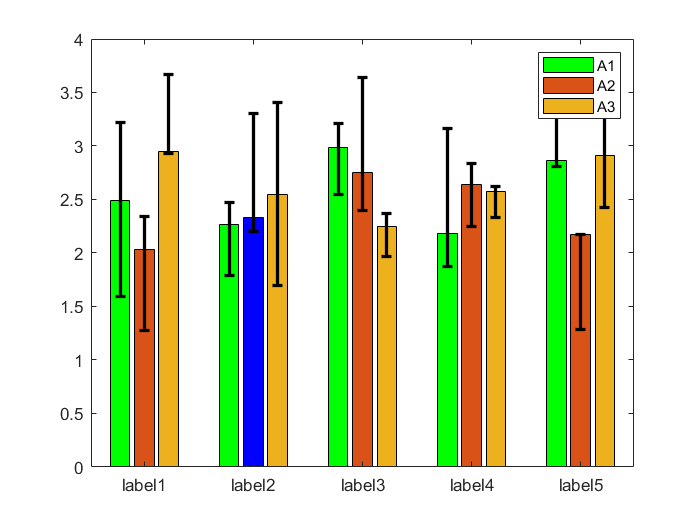

% 多系列带有误差线的柱状图
figure;
% 绘制柱状图
h = bar(x, y);
% 单独设置第二个系列第二个柱子为蓝色
h(1, 2).FaceColor = 'flat';
h(1, 2).CData(2,:) = [0, 0, 1]; 
% 设置第一个系列为绿色
h(1, 1).FaceColor = [0, 1, 0];
% 获取误差线 x 值
xx = zeros(m, n);
for i = 1 : n
    xx(:, i) = h(1, i).XEndPoints'; 
end
% 绘制误差线
hold on
errorbar(xx, y, neg, pos, 'LineStyle', 'none', 'Color', 'k', 'LineWidth', 2);
hold off
% 绘制图例
legend({'A1', 'A2', 'A3'});
% 设置 x 轴标签
set(gca, 'XTickLabel', {'label1', 'label2', 'label3', 'label4', 'label5'});

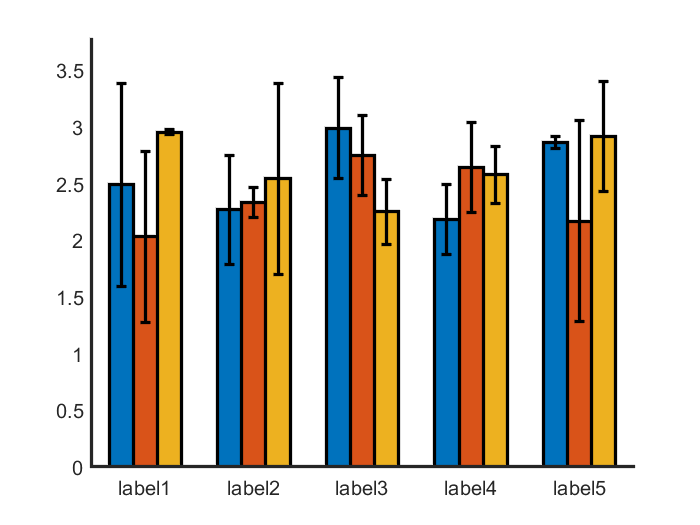

% 试试 barweb
figure;
barweb(y, neg, 1, {'label1', 'label2', 'label3', 'label4', 'label5'});